rng('default')
rng(1234)
cd /Users/serg/github_projects/QASS_SVM/data
addpath '/Users/serg/Downloads/FixedSize'
% fsllsvm.m modified to export figures

load digits; clear size
[N, dim]=size(X);
Ntest=size(Xtest1,1);
minx=min(min(X)); 
maxx=max(max(X));

noisefactor =1.0;
noise = noisefactor*maxx; % sd for Gaussian noise

Xn = X; 
for i=1:N;
  randn('state', i);
  Xn(i,:) = X(i,:) + noise*randn(1, dim);
end

Xnt = Xtest1; 
for i=1:size(Xtest1,1);
  randn('state', N+i);
  Xnt(i,:) = Xtest1(i,:) + noise*randn(1,dim);
end

%
% select training set
%
Xtr = X(1:1:end,:);

sig2 =dim*mean(var(Xtr)); % rule of thumb
sigmafactor = 0.7;
sig2=sig2*sigmafactor;


Kernel PCA: extract the principal eigenvectors in feature space


sig2 = 35.9078


disp(' ');

disp(' Denoise using the first PCs');

 Denoise using the first PCs


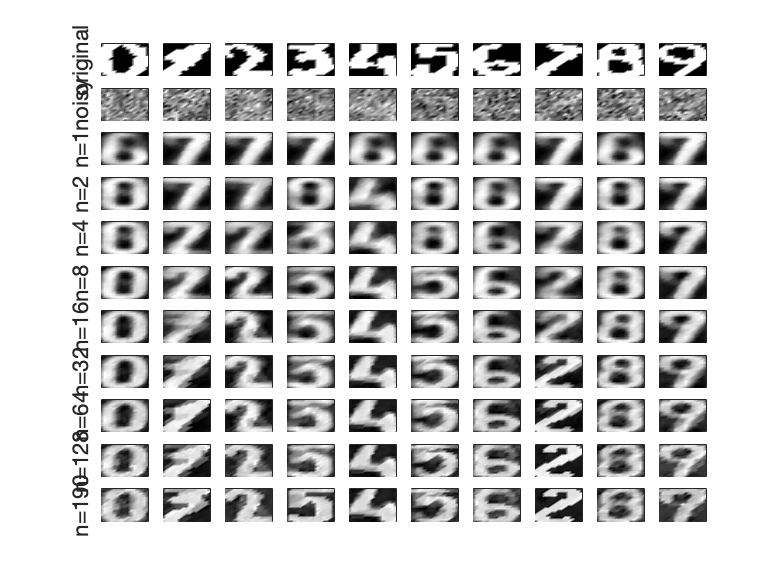

nb_pcs = 1


digit 0 : digit 1 : digit 2 : digit 3 : 

    1> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 


digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 2


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 4


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 8


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 16


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 32


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 64


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 128


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 190


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 


% choose the digits for test
digs=[0:9]; ndig=length(digs);
m=2; % Choose the mth data for each digit 

Xdt=zeros(ndig,dim);


%
% figure of all digits
%
%

% kernel PCA
[lam,U] = kpca(Xtr,'RBF_kernel',sig2,[],'eig',240); 
[lam, ids]=sort(-lam); lam = -lam; U=U(:,ids);


figure; 
colormap('gray'); 
title('Denosing using linear PCA'); tic


% which number of eigenvalues of kpca
npcs = [2.^(0:7) 190];
lpcs = length(npcs);



for k=1:lpcs;
 nb_pcs=npcs(k); 
 disp(['nb_pcs = ', num2str(nb_pcs)]); 
 Ud=U(:,(1:nb_pcs)); lamd=lam(1:nb_pcs);
    
 for i=1:ndig
   dig=digs(i);
   fprintf('digit %d : ', dig)
   xt=Xnt(i,:);
   if k==1 
     % plot the original clean digits
     %
     subplot(2+lpcs, ndig, i);
     pcolor(1:15,16:-1:1,reshape(Xtest1(i,:), 15, 16)'); shading interp; 
     set(gca,'xticklabel',[]);set(gca,'yticklabel',[]);        
     
     if i==1, ylabel('original'), end 
     
     % plot the noisy digits 
     %
     subplot(2+lpcs, ndig, i+ndig); 
     pcolor(1:15,16:-1:1,reshape(xt, 15, 16)'); shading interp; 
     set(gca,'xticklabel',[]);set(gca,'yticklabel',[]);        
     if i==1, ylabel('noisy'), end
     drawnow
   end    
   Xdt(i,:) = preimage_rbf(Xtr,sig2,Ud,xt,'denoise');
   subplot(2+lpcs, ndig, i+(2+k-1)*ndig);
   pcolor(1:15,16:-1:1,reshape(Xdt(i,:), 15, 16)'); shading interp; 
   set(gca,'xticklabel',[]);set(gca,'yticklabel',[]);           
   if i==1, ylabel(['n=',num2str(nb_pcs)]); end
   drawnow    
 end % for i
end % for k


f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures3/fig3_321_1.png','Resolution',300)

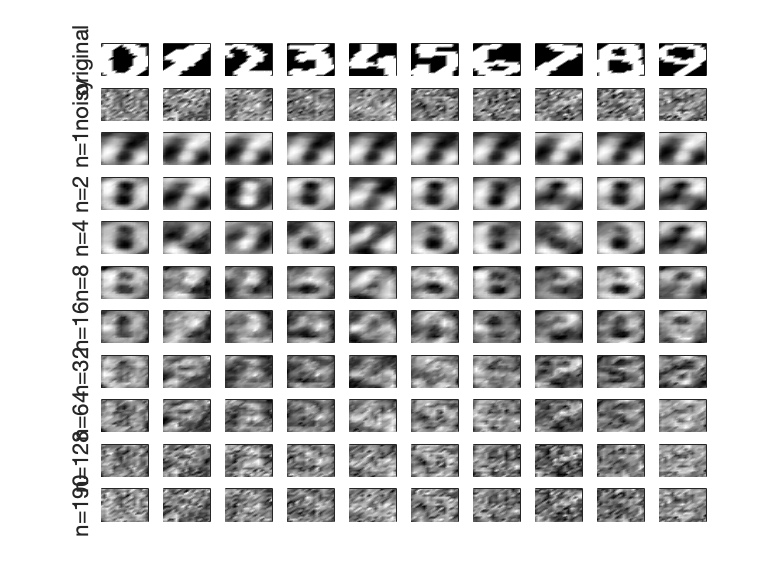


%
% denosing using Linear PCA for comparison
%

% linear PCA
[lam_lin,U_lin] = pca(Xtr);

% which number of eigenvalues of pca
npcs = [2.^(0:7) 190];
lpcs = length(npcs);


figure; colormap('gray');title('Denosing using linear PCA');

for k=1:lpcs;
 nb_pcs=npcs(k); 
 Ud=U_lin(:,(1:nb_pcs)); lamd=lam(1:nb_pcs);
    
 for i=1:ndig
    dig=digs(i);
    xt=Xnt(i,:);
    proj_lin=xt*Ud; % projections of linear PCA
    if k==1 
        % plot the original clean digits
        %
        subplot(2+lpcs, ndig, i);
        pcolor(1:15,16:-1:1,reshape(Xtest1(i,:), 15, 16)'); shading interp; 
        set(gca,'xticklabel',[]);set(gca,'yticklabel',[]);                
        if i==1, ylabel('original'), end  
        
        % plot the noisy digits 
        %
        subplot(2+lpcs, ndig, i+ndig); 
        pcolor(1:15,16:-1:1,reshape(xt, 15, 16)'); shading interp; 
        set(gca,'xticklabel',[]);set(gca,'yticklabel',[]);        
        if i==1, ylabel('noisy'), end
    end
    Xdt_lin(i,:) = proj_lin*Ud';
    subplot(2+lpcs, ndig, i+(2+k-1)*ndig);
    pcolor(1:15,16:-1:1,reshape(Xdt_lin(i,:), 15, 16)'); shading interp; 
    set(gca,'xticklabel',[]);set(gca,'yticklabel',[]);        
    
    if i==1, ylabel(['n=',num2str(nb_pcs)]), end
 end % for i
end % for k

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures3/fig3_321_2.png','Resolution',300)

sigmafactor